% 作者：FightingChiken
% 链接：https://www.zhihu.com/question/23543405/answer/1974221539734986783
% 来源：知乎
% 著作权归作者所有。商业转载请联系作者获得授权，非商业转载请注明出处。

clear
clc
close all


fs = 200e6;      % 采样频率 (100 MHz)
Ts = 1/fs;       % 采样间隔
PRI = 100e-6;    % 脉冲重复周期 (100 μs)
fc = 10e6;       % LFM信号载频 (10 MHz)
B = 10e6;        % 信号带宽 (40 MHz)
taup = 20e-6;    % 信号脉宽 (20 μs)
k = B/taup;      % 调频斜率
SNR = 15;        % 信噪比 (dB)
JSR = 15;         % 干信比 (dB)


Nr = round(fs*PRI);      % 一个PRI内的总采样点数
N_total = Nr;
Nfast = round(fs*taup);  % 一个脉宽内的采样点数
Ntau = Nfast;
samp_num = Nr; % 总信号长度

%% 生成 LFM 目标信号
As = 10^(SNR/20);        % 目标信号幅度
t_pulse = (-Nfast/2:(Nfast/2 - 1))*Ts;
lfm_pulse = exp(1j * (2*pi*fc*t_pulse + pi*k*(t_pulse.^2)));
% 创建一个完整的、未加时延的LFM信号（用于后续相乘）
lfm_full = [lfm_pulse, zeros(1, Nr-Nfast)];
% 创建一个带有时延的LFM信号（用于对比和最终合成）
range_tar = 1 + round(0.5 * (samp_num - Nfast - 1)); % 固定时延以便观察
target_signal_delayed = zeros(1, samp_num);
target_signal_delayed(1 + range_tar : Nfast + range_tar) = As * lfm_pulse;


%% 生成 梳状谱信号
% 这个信号本身不是干扰，而是用于与LFM信号相乘的"调制"信号。
% 它的频谱是一系列等间隔的尖峰，像一把梳子。

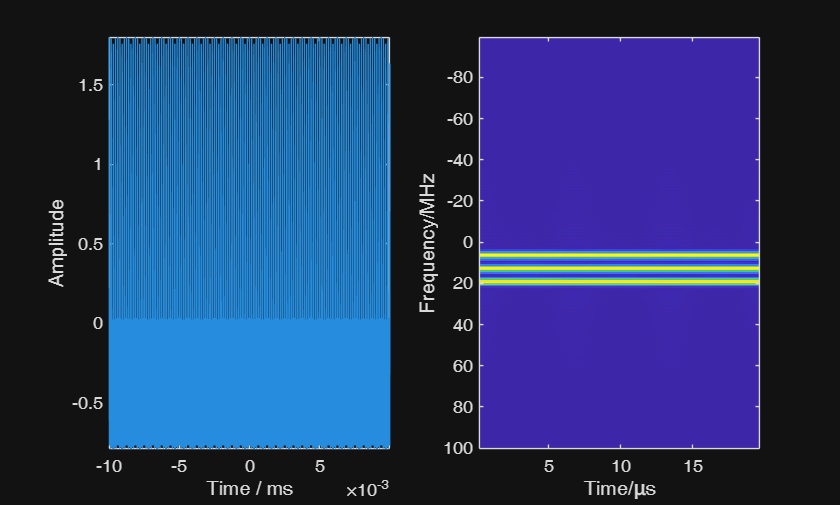

% t_pulse = params.ttau;
fs = 200e6;      % 采样频率 (100 MHz)
Ts = 1/fs;       % 采样间隔
t_pulse = (-Ntau/2:(Ntau/2 - 1))*Ts;
% --- 梳状谱参数 (固定值以便分析) ---
M = 3;                % 梳齿数量 (comb_num)
Q = 0.08;              % 梳齿频率间隔系数 (comb_fi_k)
P = 0.6;               % 梳齿幅度系数 (comb_altitude_k)

comb_signal = zeros(1, N_total);
% 生成梳状谱信号（只在LFM脉冲宽度内有定义）
comb_pulse = zeros(1, Ntau);
for i = 1:M
    % 计算第i个梳齿的频率，注意这里是相对于零频的偏移
    fi = i * Q * fc*8;
    comb_pulse = comb_pulse + P * exp(1j*2*pi*fi*t_pulse);
end
% 将生成的梳状谱脉冲放入与LFM信号相同的位置
comb_signal(1:Ntau) = comb_pulse;

subplot(1,2,1);
plot(t_pulse*1e3, real(comb_pulse));
% axis([0 3.2 -1.1 1.1])
axis tight;
xlabel('Time / ms'); ylabel('Amplitude');

subplot(1,2,2);

[S,F,T] = spectrogram(comb_pulse,128,64,256,fs, 'centered');
% S = all_S(50*i-49,:,:);
S = squeeze(S);
imagesc(T*1e6,F/1e6,abs(S));
xlabel('Time/μs'); ylabel('Frequency/MHz');

%% 生成被干扰后的信号并合成最终信号
% J0 = As * lfm .* comb;
jammed_lfm_undelayed = As * lfm_full .* comb_signal;

% 对被干扰后的信号施加时延
jammed_target_signal = zeros(1, samp_num);
jammed_target_signal(1 + range_tar : Nfast + range_tar) = jammed_lfm_undelayed(1:Nfast);

% 生成背景噪声并合成最终信号
Aj = 10^((SNR+JSR)/20); % 干扰幅度（在这里可理解为对整个被干扰信号的增益）
background_noise = (randn(1, samp_num) + 1j*randn(1, samp_num)) / sqrt(2);
J = Aj * jammed_target_signal + background_noise;





% -----------------分析 LFM 目标回波 (纯净) -------------------
figure('Name', '1. Pure LFM Target Echo Analysis', 'Position', [50, 100, 1200, 800]);
sgtitle('纯净LFM目标回波信号分析', 'FontSize', 16, 'FontWeight', 'bold');

subplot(2, 2, 1);
t_plot_us = (0:samp_num-1) * Ts * 1e6; plot(t_plot_us, real(target_signal_delayed));
grid on; title('时域波形'); xlabel('时间 (μs)'); ylabel('幅度'); xlim([0, PRI*1e6]);

subplot(2, 2, 2);
f_plot_mhz = linspace(-fs/2, fs/2, samp_num) * 1e-6; target_fft = fftshift(abs(fft(target_signal_delayed)));
plot(f_plot_mhz, 20*log10(target_fft/max(target_fft)+eps)); grid on; title('频域谱'); xlabel('频率 (MHz)'); ylabel('归一化幅度 (dB)'); ylim([-80, 5]);

subplot(2, 2, 3);
h = hamming(128); [S, F, T] = spectrogram(target_signal_delayed, h, 127, 128, fs);
f_axis_mhz = linspace(-fs/2, fs/2, 128) * 1e-6; T_axis_us = T * 1e6; imagesc(T_axis_us, f_axis_mhz, abs(fftshift(S, 1)));
axis xy; title('时频图 (完整PRI)'); xlabel('时间 (μs)'); ylabel('频率 (MHz)'); colormap('jet'); colorbar;

subplot(2, 2, 4);
imagesc(T_axis_us, f_axis_mhz, abs(fftshift(S, 1))); axis xy;
title('时频图 (聚焦LFM脉冲)'); xlabel('时间 (μs)'); ylabel('频率 (MHz)'); signal_start_time = range_tar * Ts * 1e6; signal_end_time = (range_tar + Nfast) * Ts * 1e6; xlim([signal_start_time, signal_end_time]); colormap('jet'); colorbar;

% ------------------分析梳状谱信号 (乘子) -------------------
figure('Name', '2. Comb Signal Analysis (The Multiplier)', 'Position', [100, 150, 1200, 450]);
sgtitle('梳状谱信号分析 (用于相乘的信号)', 'FontSize', 16, 'FontWeight', 'bold');
subplot(1, 3, 1); plot(t_plot_us, real(comb_signal)); grid on; title('时域波形'); xlabel('时间 (μs)'); ylabel('幅度'); xlim([0, PRI*1e6]);
subplot(1, 3, 2); comb_fft = fftshift(abs(fft(comb_signal))); plot(f_plot_mhz, 20*log10(comb_fft/max(comb_fft)+eps)); grid on; title('频域谱'); xlabel('频率 (MHz)'); ylabel('归一化幅度 (dB)'); ylim([-80, 5]);
subplot(1, 3, 3); [S, F, T] = spectrogram(comb_signal, h, 127, 128, fs); T_axis_us = T * 1e6; imagesc(T_axis_us, f_axis_mhz, abs(fftshift(S, 1))); axis xy; title('时频图'); xlabel('时间 (μs)'); ylabel('频率 (MHz)'); colormap('jet'); colorbar;

% -------------------最终合成信号 (合并后) -------------------
figure('Name', '3. Final Jammed Signal Analysis', 'Position', [150, 200, 1200, 800]);
sgtitle('最终被干扰信号分析', 'FontSize', 16, 'FontWeight', 'bold');
subplot(2, 2, 1); plot(t_plot_us, real(J)); grid on; title('时域波形'); xlabel('时间 (μs)'); ylabel('幅度'); xlim([0, PRI*1e6]);
subplot(2, 2, 2); J_fft = fftshift(abs(fft(J))); plot(f_plot_mhz, 20*log10(J_fft/max(J_fft)+eps)); grid on; title('频域谱'); xlabel('频率 (MHz)'); ylabel('归一化幅度 (dB)'); ylim([-80, 5]);
subplot(2, 2, 3); [S, F, T] = spectrogram(J, h, 127, 128, fs); T_axis_us = T * 1e6; imagesc(T_axis_us, f_axis_mhz, abs(fftshift(S, 1))); axis xy; title('时频图 (完整PRI)'); xlabel('时间 (μs)'); ylabel('频率 (MHz)'); colormap('jet'); colorbar;
subplot(2, 2, 4); imagesc(T_axis_us, f_axis_mhz, abs(fftshift(S, 1))); axis xy; title('时频图 (聚焦原始脉冲区域)'); xlabel('时间 (μs)'); ylabel('频率 (MHz)'); xlim([signal_start_time, signal_end_time]); colormap('jet'); colorbar;